Homework by Mikołaj Suchoń

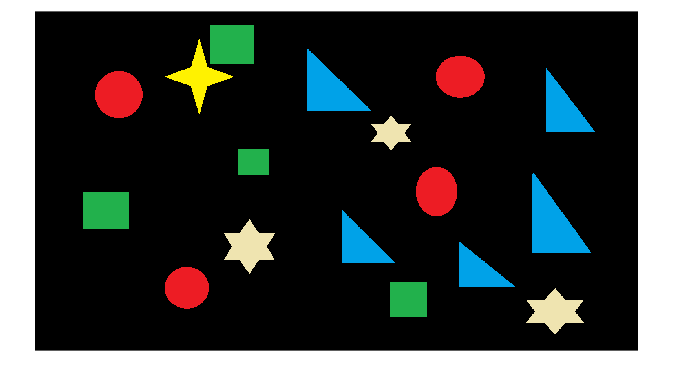

clear

I=imread("collorseg.png");
imshow(I);

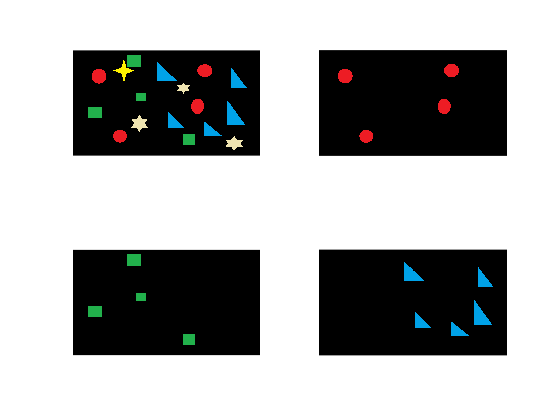

labelsim = imsegkmeans(I,6);
[ymax,xmax,cmax]=size(I);
circles=uint8(zeros(ymax,xmax,cmax));
squares=uint8(zeros(ymax,xmax,cmax));
triangles=uint8(zeros(ymax,xmax,cmax));
for y=1:ymax
for x=1:xmax
if labelsim(y,x)==1
elseif labelsim(y,x)==3
    circles(y,x,:)=I(y,x,:);
elseif labelsim(y,x)==5
    squares(y,x,:)=I(y,x,:);
elseif labelsim(y,x)==2
    triangles(y,x,:)=I(y,x,:);
end

end
end
figure
subplot(2,2,1)
imshow(I)
subplot(2,2,2)
imshow(circles)
subplot(2,2,3)
imshow(squares)
subplot(2,2,4)
imshow(triangles)

Using this method we can segment image into any set of objects of similar colour. Having labeled the objects we can add, subtract or modify any part of the image.